## **Final Project:Noise Cancellation Approach I**

**Subject: Digital Signal Processing Laboratory**

**Teacher: Luis Arturo Montesinos Silva**

Frida Berenice Rangel García            |A01651385

Luis Arturo Dan Fong                         |A01650672

Alfredo Zhu Chen                               |A01651980

José Rubén Villicaña Ibargüengoytia |A01654347

**1.Clear the enviroment**

clear all
close all
clc

**2.Read data and declare parameters**

Reading noise.wav and noise_and_voice.wav files. Its sampling frequency is *Fs*=44100 Hz and its sampling period is 1/*Fs*. The sampling time *s*, time interval t and frequency interval f are declared. 

Fs=44100;                               %Sampling frequency
Ts=1/Fs;                                %Sampling period
noise= audioread('noise.wav');          %Read noise data                               
voice= audioread('noise_and_voice.wav');%Read noise+voice data
samples_voice=length(voice);            %Length of voice+noise
samples_noise=length(noise);            %Length of noise(shoud be equal to voice+noise) 
s=Ts*samples_noise;                     %Sampling time in seconds            
t=(0:Ts:s-Ts)';                         %time interval
f=Fs*[0:samples_noise-1]/samples_noise-Fs/2;%frequency interval

**3. Listen to the noise and input(signal of interest+noise) signal. **

sound(noise,Fs);                       %play noise
pause(s)                               %Pause until finish playing
sound(voice,Fs);                       %play noise+voice
pause(s)                               %Pause until finish playing

**4. Apply Fast Fourier Transform(FFT) to both signals**

noise_fourier = abs(fft(noise));        %fft magnitude of noise
voice_fourier = abs(fft(voice));        %fft magnitude of voice+noise

**5. Plot of noise in time and frequency domain in the same figure**

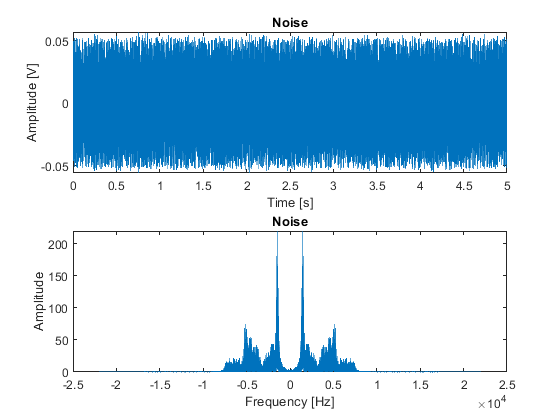

figure 
subplot(2,1,1)
plot(t,noise);                          %noise in time domain
xlabel("Time [s]")
ylabel("Amplitude [V]")
title("Noise")
subplot(2,1,2)
plot(f,fftshift(noise_fourier));        %noise in frequency domain
ylabel("Amplitude")
xlabel("Frequency [Hz]")
title("Noise")
subplot(2,1,2)

**6. Plot of input signal in time and frequency domain in the same figure**

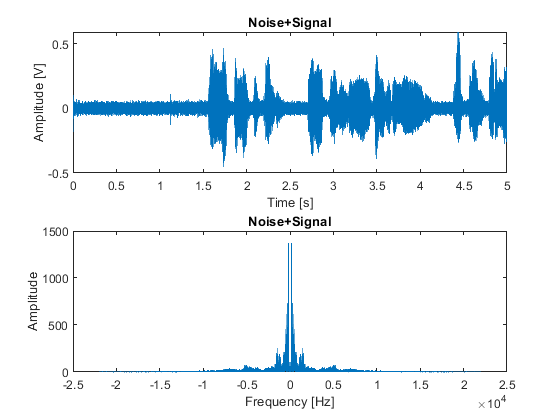

figure
subplot(2,1,1)
plot(t,voice);                          %voice+noise in time domain
xlabel("Time [s]")
ylabel("Amplitude [V]")
title("Noise+Signal")
subplot(2,1,2)
plot(f,fftshift(voice_fourier));        %voice+noise in frequency domain
xlabel("Frequency [Hz]")
ylabel("Amplitude")
title("Noise+Signal")

**7. Spectrogram of input signal**

Analysis of input signal in the frequency and time-frequency domains.

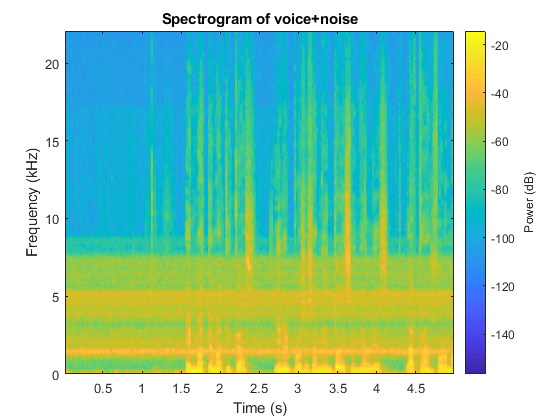

figure
pspectrum(voice,t,"spectrogram")
title("Spectrogram of voice+noise")

**8. Find local maxima of noise above a threshold value.**

The threshold value is a parameter to determine which components of frequency in the input signal should be attenuated. 

The islocalmax(*A*) function finds the local maxima indices of the signal above the threshold. In this case, it finds local maxima of noise_fourier above MinProminence value according to f SamplePoints. A plot is generated to see the result.

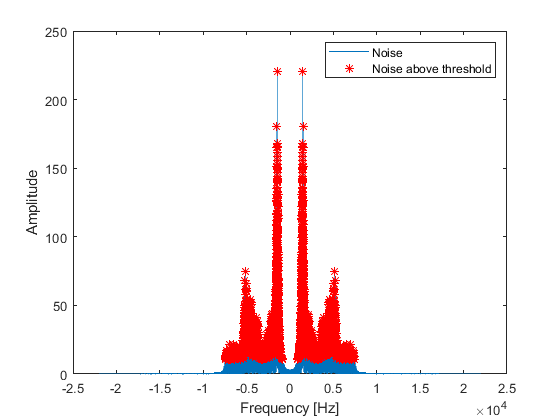

 
threshold = 10;                         %Knob that changes the threshold
noise_fourier_shifted = fftshift(noise_fourier);
maxIndices = islocalmax(noise_fourier_shifted,"MinProminence",threshold,"SamplePoints",f);

figure %Plotting noise_fourier with the local maxima
plot(f,noise_fourier_shifted,f(maxIndices),noise_fourier_shifted(maxIndices),'r*')
xlabel("Frequency [Hz]")
ylabel("Amplitude")
legend("Noise","Noise above threshold")

**9. Declare f0 Vector which contains the frequency interval to analyze, it also determines which frecuencies components will be attenuated**

Since the fourier transform is symmetric by y-axis, only half of the frequeny interval is necessary to analyze and the local max indices determine the high values of frequency components of the noise signal 

if mod(samples_noise,2)==0 %Even samples_noise
    f0=f(samples_noise/2+1:end);        %Reading half of frequency interval
    max_f0 = maxIndices(samples_noise/2+1:end);%maxima in the half frequency interval
    f0_vector = f0'.*max_f0;
else
    f0=f((samples_noise+1)/2:end);      %Reading half of frequency interval
    max_f0 = maxIndices((samples_noise+1)/2:end);%maxima in the half frequency interval
    f0_vector = f0'.*max_f0;
end

**10. Filter the input signal**

Infinite Impulse Response(IIR) filters are used to attenuate the noise. The notch filters are located at *w0*  and the bandwidth at the -3dB point set by variable *bw*. *w0* is the normalized frequency(0<*w0*<1 ) corresponding to π radians per sample in the frequency range. The attenuation value in dB is scaled by an attenuation proportion. The coefficients of the notch filters 'a' and 'b' are used as arguments for the filter function in MATLAB. The result of each iteration of the signal filtered is stored in the voice_filtered variable. 

%% Filtering
bw = (1/(Fs/2))*2;                      %Knob that changes the bandwith
voice_filtered = voice;                 %Initialize voice_filtered
attenuation_factor = 7;                 %Knob that changes how much in dB each component is affected
m = max(noise_fourier);             %Maximum value in frequency domain
for i = 1:samples_noise/2  
    w0 = f0_vector(i,1)/(Fs/2);         %Normalized frequency where notch is located
    if w0 ~= 0                          %Check if contains frequencies
        at = noise_fourier(i,1)/m;      %attenuation proportion
        [b,a] = iirnotch(w0,bw,at*attenuation_factor);%Obtaining coefficients of filter notch
        voice_filtered=filter(b,a,voice_filtered); %Filtering 
    end
end
voice_fourier_filtered = fft(voice_filtered);%FFT of voice_filtered

**11. Change of Amplitude(Volumen) in Frequency Domain**

This section establishes which components in the frequency domain according to a constant gain_loss_threshold value are amplfied and attenuated. It is useful to have a greater Signal-Noise Ratio(SNR) value as the signal of interest is amplyified and the noise is attenuated.

gain_loss_threshold=3;%Threshold value to attenuate and amplify components
gain=2; %gain factor value from 0 to 10, try low values first
loss=0.6;%loss factor value from 0 to 1
for i = 1:samples_noise
    if abs(voice_fourier_filtered(i,1)) >gain_loss_threshold;
        voice_fourier_filtered(i,1) = voice_fourier_filtered(i,1)*gain;%Amplifying signal above threshold
    else
        voice_fourier_filtered(i,1) = voice_fourier_filtered(i,1)*loss;%Noise attenuation below threshold
    end
end

**12. Plots of the input signal and the filtering result**

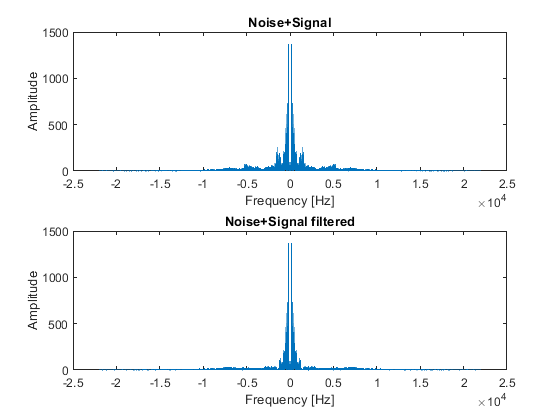

figure
subplot(2,1,1)
plot(f,fftshift(voice_fourier));        %Noise+Voice in frequency
xlabel("Frequency [Hz]")
ylabel("Amplitude")
title("Noise+Signal")
subplot(2,1,2)
plot(f,fftshift(abs(fft(voice_filtered))));%Noise+Voice filtered in frequency
xlabel("Frequency [Hz]")
ylabel("Amplitude")
title("Noise+Signal filtered")

**13.Spectrogram of the input signal filtered**

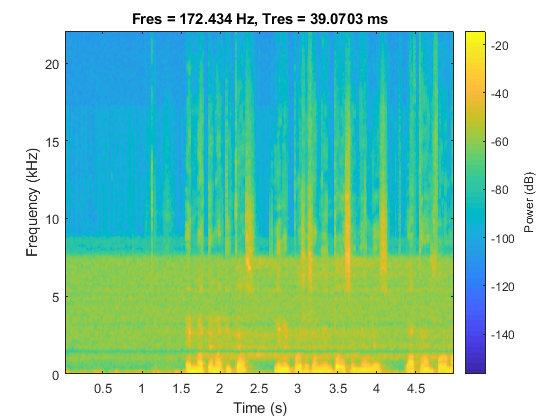

figure
pspectrum(voice_filtered,t,"spectrogram")

**14. Listen to the input signal and the signal filtered**

sound(voice,Fs);                        %play noise+voice
pause(s)
sound(voice_filtered,Fs);               %play noise+voice filtered